clc
clear all
close all
load('Received.mat')

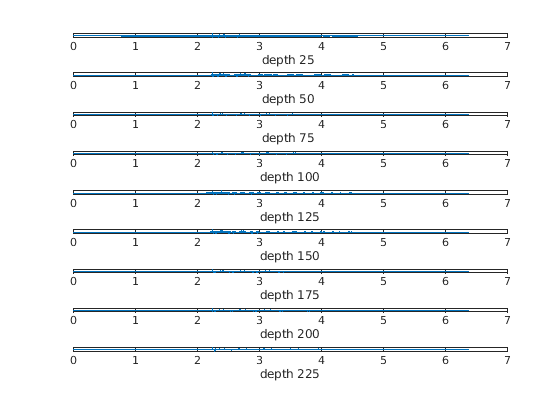

C = 1500; % speed in m/s
dt = 2e-4;
%looking for at which depth the signal came at first
%it will be near that depth
t = dt:dt:6.4;
x_labels = ['depth 25 '; 'depth 50 '; 'depth 75 '; 'depth 100'; 'depth 125'; 'depth 150'; 'depth 175'; 'depth 200'; 'depth 225'];
for i = 1:size(RecSig,1)
    this_signal = RecSig(i,:);
    
    subplot(9,1,i)
    plot(t, this_signal);
    xlabel(x_labels(i,:))
    hold off
end

%the first peak is the highest point in the signal
%to find this we square up the signal to make all
% the negative to positive
%then we take the values up to first 0.5
%let it be the fist arrival point
for i = 1:size(RecSig,1)
    this_signal = RecSig(i,:);
    sq_signal = abs(this_signal);
    needed_signal = sq_signal( 1:find( sq_signal > 0.5, 1 ) );
    
    
    time_of_coming(i) = t(size(needed_signal,2));
    
end

%lowest value of time is
[min, minIndex] = min(time_of_coming);
%so the nearest depth of the reciver from the source is
estimated_depth = minIndex*25

estimated_depth = 125

%so lets assume the source was at this depth
% lets form a right angle triangle with the reciever at 125m
% and the first reciever at 25m with the source
%find the time for the signal to reach them first


t_25 = time_of_coming(1)

t_25 = 2.2472

t_125 = time_of_coming(5)

t_125 = 2.2444


%time difference
Del_T = t_25-t_125

Del_T = 0.0028

%distance covered in Del_T
del_d = Del_T*C

del_d = 4.2000


%so D_25 - D_125 = del_d 
%or D_25 = D_125 + del_d 
%finding the distance of the recievers from
%the source
%from pythagorus theorem
syms d_125 d_25;
d_25 = d_125+del_d

$$d\_25 = d_{125}+\frac{1182194902184625}{281474976710656}$$


eq1 = d_125^2 +100^2 -d_25^2;
val_d125 = solve(eq1==0, d_125)

$$val\_d125 = \frac{6327072322847136486910735335755}{5324132520957977117614669824}$$

distance_in_x = vpa(val_d125,7)

$$distance\_in\_x = 1188.376$$

%so the distance roughly 1188.376
%so we will search around this point
